## Code to process moment balance data

**Load data files :**

clear
static_test = 1;
addpath(genpath(fullfile(pwd,'sw')))

switch static_test
    case 1
        % First Static test
        %p = parselog(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1605\test_act_6ms\22_05_16__15_59_59_SD_no_GPS.data'));
        %p = parselog(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1605\test_act_9ms\22_05_16__17_38_04_SD_no_GPS.data'));
        %p = parselog(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1605\test_act_12ms\22_05_16__18_46_42_SD_no_GPS.data'));
        %p = parselog('fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1605\test_act_15ms\22_05_16__20_10_18_SD_no_GPS.data'));
        p = parselog(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1605\test_act_18ms\22_05_16__21_27_36_SD_no_GPS.data'));
        save_path=fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1605\database_2\single');
    case 2
        % Second static test
        %p = parselog(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1805\5_deg\22_05_18__20_15_05_SD_no_GPS.data'));
        p = parselog(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1805\8_deg\22_05_19__13_29_01_SD_no_GPS.data'));
        save_path = fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1805\database_2\single');
    case 3
        % Third static test
        p = parselog(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1905\turn_table_test\22_06_08__11_43_56_SD_no_GPS.data'));
        save_path = fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1905\database_2\single');
end 
drone = p.aircrafts.data.WINDTUNNEL_STATIC;
% Windtunnel
meas_list = 8; %4
name = 'v18.xlsx';
temp = WTApril2022(meas_list,0,static_test);
wind_tunnel_data = temp.data{1,1};

**Data Windtunnel :**

% Remember to create bias files for new data files if not already there
% automatic_bias(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1605\OJF'),fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1605\OJF\bias'))
switch static_test
    case 1
        % First static test
        txtFiles = dir(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1605\OJF\bias','*.txt')); 
        fid = fopen(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1605\OJF\bias',txtFiles(meas_list).name));
    case 2    
        % Second static test
        txtFiles = dir(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1805\OJF\bias','*.txt')); 
        fid = fopen(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1805\OJF\bias',txtFiles(meas_list).name));
    case 3    
        % Third static test
        txtFiles = dir(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1905\OJF\bias','*.txt')); 
        fid = fopen(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1905\OJF\bias',txtFiles(meas_list).name));
end
format = sprintf('%s', repmat('%f', 1, 6));
Bias = cell2mat(textscan(fid, format,'Delimiter', ','));
fclose(fid);

time_wt = wind_tunnel_data.t; %[s]
airspeed_wt = wind_tunnel_data.V; %[m/s]
Mx = wind_tunnel_data.Mx-Bias(4); %[Nm]
My = wind_tunnel_data.My-Bias(5); %[Nm]
Mz = wind_tunnel_data.Mz-Bias(6); %[Nm]
Fx = wind_tunnel_data.Fx-Bias(1); %[N]
Fy = wind_tunnel_data.Fy-Bias(2); %[N]
Fz = wind_tunnel_data.Fz-Bias(3); %[N]
tt = wind_tunnel_data.angle;      %[deg]

**Data Drone :**

test_active = drone.test_active;%ones(size(drone.timestamp));
time_dr = drone.timestamp(test_active==1);
airspeed_dr = drone.airspeed(test_active==1);
act = cellfun(@(S) sscanf(S, '%f,').', drone.u(test_active==1,:), 'Uniform', 0);
act = cell2mat(act);
thrust_quad = sum(act(:,1:4),2);
pitch = drone.theta_alt(test_active==1);
skew_sp = drone.wing_angle_deg_sp(test_active==1);
skew    = drone.wing_angle_deg(test_active==1);
wind_counter = drone.wind_counter(test_active==1); %[-]p
wing_counter = drone.wing_counter(test_active==1); %[-]i
mot_status_counter = drone.mot_status_counter(test_active==1); %[-]j
as_counter = drone.as_counter(test_active==1); %[-]k
excitation_counter = drone.excitation_counter(test_active==1); %[-]n
test_point_counter = drone.test_point_counter(test_active==1); %[-]

**Synch time arrays :**

Before start of the test the drone will automatically perform 3 burst in push prop command of increasing strenght. The balance will then generate readings in the forward force. Plot the two signal and find a dt which syncs them. 

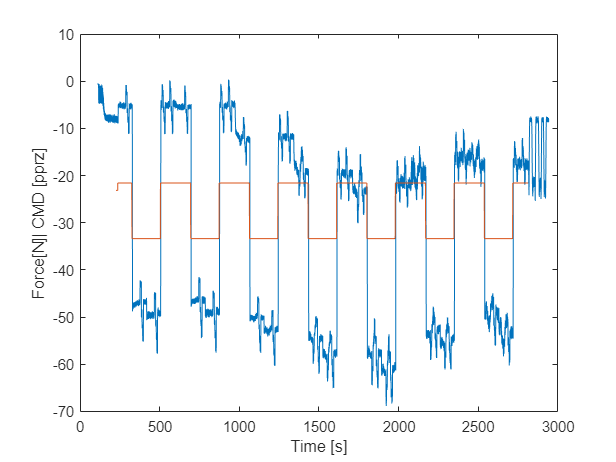

%dt = 173.122;%88.7610;149.622
switch static_test
    case 1
        % First static test
        txtFiles = dir(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1605\OJF\sync_times','*.txt')); 
        fid = fopen(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1605\OJF\sync_times',txtFiles(meas_list).name));
    case 2    
        % Second static test
        txtFiles = dir(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1805\OJF\sync_times','*.txt')); 
        fid = fopen(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1805\OJF\sync_times',txtFiles(meas_list).name));
    case 3    
        % Third static test
        txtFiles = dir(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1905\OJF\sync_times','*.txt')); 
        fid = fopen(fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1905\OJF\sync_times',txtFiles(meas_list).name));
end

format = sprintf('%s', repmat('%f', 1, 1));
dt = cell2mat(textscan(fid, format,'Delimiter', ','));
fclose(fid);
if static_test<2
    figure(1)
    clf
    plot(time_wt+dt,Fz)
    hold on
    plot(time_dr,act(:,1)./500.*-9.81)
    xlabel("Time [s]")
    ylabel("Force[N]| CMD [pprz]")
else
    figure(1)
    clf
    plot(time_wt+dt,Fy)
    hold on
    plot(time_wt+dt,Fy)
    hold on
    plot(time_dr,skew_sp./-10)
    xlabel("Time [s]")
    ylabel("Turn table [deg]| Pitch [deg]")
end

time_wt_sync = time_wt+dt;

**Perform Moment and Force Calculations :**

counter = 0;
test_point = 0;
wing_id = 5;
database_header = ["ID","Item","Windspeed","Airspeed","Skew","Skew_sp","Mot_Status","Excitation","Mx","My","Mz","Fx","Fy","Fz","Mot_F","Mot_R","Mot_B","Mot_L","Ail_L","Ail_R","Elev","Rud","Pitch","std_Mx","std_My","std_Mz","std_Fx","std_Fy","std_Fz"];
database = double([]);
pitch_s = mean(pitch);
disp('Start')

Start


delay = 0.5;
for p=0:max(wind_counter)
    Airspeed_s = mean(airspeed_dr(wind_counter==p)) ;
    t_s = time_dr(find((wind_counter==p),1,"first"));
    t_e = time_dr(find((wind_counter==p),1,"last"));
    range = t_range(time_wt_sync,[t_s,t_e]);
    Windspeed_s = mean(airspeed_wt(range));
    for i=0:max(wing_counter)-1
        Skew_s = mean(skew(wing_counter==i));
        Skew_sp_s = round(mean(skew_sp(wing_counter==i)));
        jmax = max(mot_status_counter)-1 + double((static_test==3));
        for j=0:jmax
            test_point = test_point+1;
            if static_test<3
                Sifter = (test_point_counter==test_point).*(wing_counter==i);
            else
                Sifter = (wind_counter==p).*(wing_counter==i);
            end
            mot_s = mean(act(Sifter==1,1:4));
            t_s = time_dr(find(Sifter,1,"first"));
            t_e = time_dr(find(Sifter,1,"last"));
            range = t_range(time_wt_sync,[t_s+delay,t_e]);
            [std_mx, Mx_s] = std(Mx(range));
            [std_my, My_s] = std(My(range));
            [std_mz, Mz_s] = std(Mz(range));
            [std_fx, Fx_s] = std(Fx(range));
            [std_fy, Fy_s] = std(Fy(range));
            [std_fz, Fz_s] = std(Fz(range));

            if static_test<3
                pitch_s = mean(pitch(Sifter==1));
            else
                pitch_s = round(mean(tt(range)));
            end
            database = [database;[double(test_point),double(wing_id),Windspeed_s,Airspeed_s,Skew_s,Skew_sp_s,double(j),double(0),Mx_s,My_s,Mz_s,Fx_s,Fy_s,Fz_s,mot_s(1),mot_s(2),mot_s(3),mot_s(4),0,0,0,0,pitch_s,std_mx,std_my,std_mz,std_fx,std_fy,std_fz]];
            for k=0:max(as_counter)-1
                if j>2 && k<2
                    %test_point =test_point +5;
                    %break
                    %disp('Push prop Test');
                else
                for n=0:max(excitation_counter)-1
                    test_point = test_point +1;
                    Sifter = (wind_counter==p).*(wing_counter==i).*(mot_status_counter==j).*(as_counter==k).*(excitation_counter==n).*(test_point_counter==test_point);
                    t_s = time_dr(find(Sifter,1,"first"));
                    t_e = time_dr(find(Sifter,1,"last"));
                    range = t_range(time_wt_sync,[t_s,t_e]);
                    [std_mx, Mx_s] = std(Mx(range));
                    [std_my, My_s] = std(My(range));
                    [std_mz, Mz_s] = std(Mz(range));
                    [std_fx, Fx_s] = std(Fx(range));
                    [std_fy, Fy_s] = std(Fy(range));
                    [std_fz, Fz_s] = std(Fz(range));
                    act_s = mean(act(Sifter==1,1:8));
                    database = [database;[double(test_point),double(k),Windspeed_s,Airspeed_s,Skew_s,Skew_sp_s,double(j),double(n),Mx_s,My_s,Mz_s,Fx_s,Fy_s,Fz_s,act_s(1),act_s(2),act_s(3),act_s(4),act_s(5),act_s(6),act_s(7),act_s(8),pitch_s,std_mx,std_my,std_mz,std_fx,std_fy,std_fz]];
                end 
                    
                end
            end
        end
    end
end

**Convert to table and save**

Table = array2table(database,'VariableNames',database_header);
table_path_format = fullfile(save_path,name);
writetable(Table,table_path_format);